clear all, close all, clc

## HW04-4

We know, from Legendre polynomial-

$P_1 \left(\omega_s \;\right)=\omega$;     $P_2 \left(\omega_s \right)=\frac{3\omega^2 -1}{2}$;     $P_3 \left(\omega_s \right)=\frac{5\omega^3 -3\omega }{2}$    Here, $\omega =\cos \;\theta_s$

Now, the given equation for CS of 1-MeV neutron on Mg target, is-


$$\sigma_s {\left(E,\omega_s \right)}={\left(\frac{2.7}{4\pi }{\left(1+1.2\omega +0\ldotp 75{\left(\frac{3\omega^2 -1}{2}\right)}+0\ldotp 08{\left(\frac{5\omega^3 -3\omega }{2}\right)}\right)}\right)}$$


Let's build the given equation-

syms w
    P1 = w;
    P2 = (3*w^2 -1)/2;
    P3 = (5*w^3 -3*w)/2;
sg_E_w = 2.7/(4*pi) *(1 + 1.2*P1 + 0.75*P2 + 0.08*P3);

### (a)

For total scattering, let's integrate the given equation over the range of scatter-cosine

sg_E = int(sg_E_w, w, -1, 1);           % scattering CS; barn
sg_E = double(sg_E)                     % barn

sg_E = 0.4297

(Ans)

### (b)

To find the mean cosine of lab scattering angle, we use following equation-


$${\left⟨\omega_s \right⟩}=\frac{\int_{-1}^1 \omega \sigma {\left(E,\omega \right)}d\omega }{\int_{-1}^1 \sigma {\left(E,\omega \right)}d\omega }$$


Here,

w_sg_E_w = sg_E_w * w;

Let's evaluate the two integrals-


$$\int_{-1}^1 \omega \sigma {\left(E,\omega \right)}d\omega$$


Nm = int(w_sg_E_w, w, -1, 1);           % numerator; b
Nm = double(Nm)

Nm = 0.1719

And, $\int_{-1}^1 \sigma {\left(E,\omega \right)}d\omega$

Dnm = int(sg_E_w, w, -1, 1);            % donominator; b
Dnm = double(Dnm)

Dnm = 0.4297

Then we have-

w_sM = Nm/Dnm                   % Mean cosine of scattering 

w_sM = 0.4000

(Ans)

### (c)

From eqn (3.32) of textbook, we come to know-

$\omega_c =-\gamma {\left(1-\omega_s^2 \right)}\pm \omega_s \sqrt{1-\gamma^2 \left(1-\omega_s^2 \right)}$     $\omega_c =$ cosine of scatter for COM-CS

And, $\gamma ={{\left(A^2 +\frac{A{\left(A+1\right)}Q}{E}\right)}}^{-\frac{1}{2}}$

Now, let's find the $\gamma$

A = 24;         % mass no. of Mg
Q = 0;          % assuming elastic collision
E = 1;          % incident nu' energy; MeV
gm = (A^2 + A*(A+1)*Q ./E).^-0.5     % gamma const.

gm = 0.0417

Now, let's define the range of $\omega_s$

w_s = linspace(-1, 1, 1001);     % cosine of scatter

Therefrom we can find the range of $\omega_c$ for different values of $\omega_s$, as follows-

w_c1 = -gm*(1- w_s.^2) + w_s .*sqrt(1 - gm^2 *(1 - w_s).^2);
w_c2 = -gm*(1- w_s.^2) - w_s .*sqrt(1 - gm^2 *(1 - w_s).^2);

Now, the given equation for differential CS, for $\omega_c$, becomes-


$$\sigma_s {\left(E,\omega_c \right)}={\left(\frac{2.7}{4\pi }{\left(1+1.2\omega_c +0\ldotp 75{\left(\frac{3{\omega_c }^2 -1}{2}\right)}+0\ldotp 08{\left(\frac{5{\omega_c }^3 -3\omega_c }{2}\right)}\right)}\right)}$$


let's find the array of  $\sigma_s {\left(E,\omega_c \right)}$ for both limitting values of $\omega_c$-

    P1 = w_c1;
    P2 = (3*w_c1.^2 -1)/2;
    P3 = (5*w_c1.^3 -3.*w_c1)/2;
sg_E_w_c1 = 2.7/(4*pi) *(1 + 1.2.*P1 + 0.75 .*P2 + 0.08 .*P3);

And-

    P1 = w_c2;
    P2 = (3*w_c2.^2 -1)/2;
    P3 = (5*w_c2.^3 -3.*w_c2)/2;
sg_E_w_c2 = 2.7/(4*pi) *(1 + 1.2.*P1 + 0.75 .*P2 + 0.08 .*P3);

Now, let's find the following-

$\sigma \left(E\right)=\int_{-1}^1 \sigma \left(E,\omega_c \right)d\omega$     through numerical integration.

w_c = linspace(1, -1, 1001);        % dicretizing
d_wc = abs(w_c(2) -w_c(1));         % elemental value

Now, let's numerically integrate this-

y = sg_E_w_c1;                      % defining new variable
l = length(w_c);
Y_S = 0;                % initializer, sum
for i = 1:1:l-1
    Y(i) = ( y(i) + y(i+1))/2 *d_wc;   % loop variable; trapezoidal rule
    Y_S = Y(i) + Y_S;
end

sg_E = Y_S                  % barn

sg_E = 0.4157

Now, let's find the following moment-


$$\omega \_\sigma \left(E\right)=\int_{-1}^1 \omega \;\sigma \left(E,\omega_c \right)d\omega$$


sg_E_wc = sg_E_w_c1;        % defining new variable
w_c = w_c1;                 % 
w_sg_E_wc = sg_E_wc .*w_c;

Now, let's numerically integrate this-

y = w_sg_E_wc;               % defining new variable
l = length(w_c);
Y_S = 0;                    % initializer, sum
for i = 1:1:l-1
    Y(i) = ( y(i) + y(i+1))/2 *d_wc;   % loop variable; trapezoidal rule
    Y_S = Y(i) + Y_S;
end

w_sg_E = Y_S                % barn

w_sg_E = 0.1570

Then, we have


$$\left\lbrace \omega_c \right\rbrace =\frac{\int_{-1}^1 \omega \;\sigma \left(E,\omega_c \right)d\omega }{\int_{-1}^1 \sigma \left(E,\omega_c \right)d\omega }=\frac{\omega \_\sigma \left(E\right)}{\sigma \left(E\right)}$$


w_cM = w_sg_E /sg_E

w_cM = 0.3776

(Ans)

### (d)

Using Table 3.4 from textbook, we get, the energy loss for nu' in isotropic/elastic is

$1-\frac{{\left⟨E^{\prime } \right⟩}}{E}=\frac{1-\alpha }{2}$; 

Or, $E-{\left⟨E^{\prime } \right⟩}=E\frac{1-\alpha \;}{2}$    Which is average energy loss.

Here, $\alpha ={{\left(\frac{A-1}{A+1}\right)}}^2$   

So, we have-

A = 24;                 % mass no. of Mg
al = ( (A-1)/(A+1))^2   % mass-no. factor

al = 0.8464

Then, 

E = 1;                  % incident nu' energy; MeV
Dl_E = E* (1-al)/2      % avg. energy loss; MeV

Dl_E = 0.0768

### (e)

We previously found two arrays of $\omega_c$ ($\omega_{\textrm{c1}} ,\omega_{c2}$) for a single array of $\omega_s$, as these two represents bound of possible $\omega_c$ for certain value of  $\omega_s$. 

To verify, how $\omega_c \;$and $\omega_s \;$are associated, let's check through a curve-

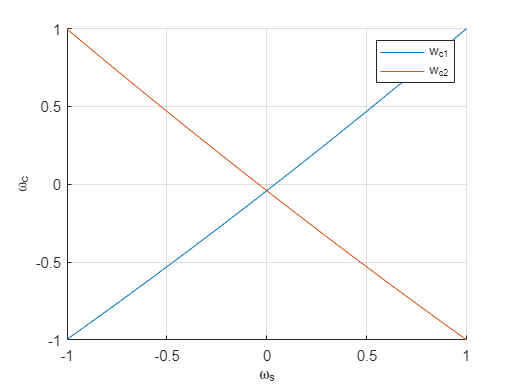

figure()
grid on, hold on
plot(w_s, w_c1, 'DisplayName', 'w_{c1}')
plot(w_s, w_c2, 'DisplayName', 'w_{c2}')
legend
xlabel('\omega_s')
ylabel('\omega_c')

So, it looks like a 45 deg linear relationship, which means, they're almost the same

Now, here's the plot of $\omega_c$ vs $\sigma \;\left(E,\omega_c \right)$, as they were found earlier in part (c)

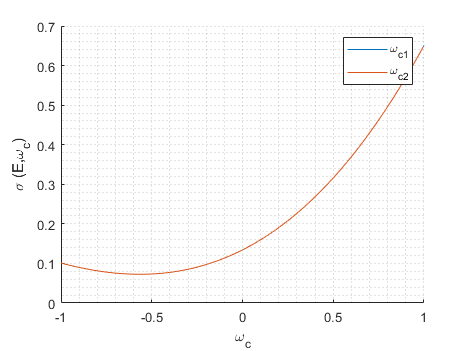

figure()
grid minor, hold on
plot(w_c1, sg_E_w_c1, 'DisplayName', '\omega_{c1}')
plot(w_c2, sg_E_w_c2, 'DisplayName', '\omega_{c2}')
legend
xlabel('\omega_c');
ylabel('\sigma (E,\omega_{c})')

So, as we see- two values are overlapping, so we can say $\sigma \left(E,\omega_{\textrm{c1}} \right)=\sigma \left(E,\omega_{\textrm{c2}} \right)=\sigma \left(E,\omega_c \right)$